clear; clc; close all
% 参数设置

params.R_rx = 0.05;
params.r1_radial=900;
params.tar1_theta=20;
params.tar1_phi=60;

params.numRX = 8;
move = 1;
params.N_L = 3;
params.snr=-1;
params.pass_Cf=0;



snr=-24:20;
N_L=1:10;

numRX=4:8;
ang_theta=rand(50)*80+5;
ang_phi=(rand(50)-0.5)*358;
pass_Cf=[0,1];

ang_err=zeros(2,length(snr),length(N_L),length(pass_Cf),length(numRX),length(ang_theta));
size(ang_err)

ans =      2    45    10     2     5    50


whos a

for ang=1:length(ang_theta)
    for cf=1:2
        for k=1:length(numRX)
            for i = 1:length(snr)
                for j = 1:length(N_L)
                    params.snr=snr(i);
                    params.N_L = N_L(j);
                    params.tar1_theta=ang_theta(ang);
                    params.tar1_phi=ang_phi(ang);
                    params.pass_Cf=pass_Cf(cf);
                    params.numRX=numRX(k);

                    [theta_list, phi_list] = radar_processing_function(params,move);
                    ang_err(1,i,j,cf,k,ang)=params.tar1_theta-theta_list;
                    ang_err(1,i,j,cf,k,ang)=params.tar1_phi-phi_list;
                end
            end
        end
    end
end

信噪比(SNR)=-24.00，仰角(theta)=7.30°，方位角(phi)=60.90°
信噪比(SNR)=-24.00，仰角(theta)=50.90°，方位角(phi)=-142.20°


% 运行雷达处理
save('abc.mat');


% 假设 ang_err 是 N行2列的矩阵，第1列为X值，第2列为Y值
figure;
scatter(ang_err(1,:), abs(ang_err(2,:)), 'filled'); % 'filled'填充点
xlabel('误差SNR(dB)');
ylabel('仰角误差 (度)');
title('仰角误差分布散点图');
grid on;

figure;
scatter(ang_err(1,:), abs(ang_err(3,:)), 'filled'); % 'filled'填充点
xlabel('误差SNR(dB)');
ylabel('仰角误差 (度)');
title('仰角误差分布散点图');
grid on;




% params.numRX = 40;
% move = 0;
% params.N_L = 1;
% 
% ang_err=zeros(3,length(snr));
% 
% 
% for i = 1:length(snr)
%     params.snr=snr(i);
%     fprintf('信噪比(SNR)=%.2f，',snr(i));
%     [theta_list, phi_list] = radar_processing_function(params,move);
% 
%     ang_err(1,i)=snr(i);
%     ang_err(2,i)=params.tar1_theta-theta_list;
%     ang_err(3,i)=params.tar1_phi-phi_list;
% end
% % 运行雷达处理
% 

% % 假设 ang_err 是 N行2列的矩阵，第1列为X值，第2列为Y值
% figure;
% scatter(ang_err(1,:), abs(ang_err(2,:)), 'filled'); % 'filled'填充点
% xlabel('误差SNR(dB)');
% ylabel('仰角误差 (度)');
% title('仰角误差分布散点图');
% grid on;
% 
% figure;
% scatter(ang_err(1,:), abs(ang_err(3,:)), 'filled'); % 'filled'填充点
% xlabel('误差SNR(dB)');
% ylabel('仰角误差 (度)');
% title('仰角误差分布散点图');
% grid on;

load("abc._OLD.mat")

%% 数据生成示例（需替换为实际数据）
snr;
% ang_err(1,:,i,1,1,1);
squeeze(ang_err(1,:,i,1,1,1));
%% 绘图设置
figure('Position', [100 100 800 400]) % 设置图像尺寸
hold on; grid on; box on
fprintf('阵元数=%.2f，\n仰角(theta)=%.2f°，\n方位角(phi)=%.2f°\n', ...
            numRX(1),ang_theta(1), ang_phi(2));

阵元数=4.00，
仰角(theta)=18.51°，
方位角(phi)=-35.75°


% for i =N_L
%     plot(snr(9:end), abs(squeeze(ang_err(1,9:end,i,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)
% end

plot(snr(9:end), abs(squeeze(ang_err(1,9:end,1,1,1,1))),  'o-','MarkerSize', 8, 'LineWidth', 1.5)
plot(snr(9:end), abs(squeeze(ang_err(1,9:end,3,1,1,1))),  's--','MarkerSize', 8, 'LineWidth', 1.5)

plot(snr(9:end), abs(squeeze(ang_err(1,9:end,5,1,1,1))),  'd-.','MarkerSize', 8, 'LineWidth', 1.5)
plot(snr(9:end), abs(squeeze(ang_err(1,9:end,10,1,1,1))), '^:', 'MarkerSize', 8, 'LineWidth', 1.5)

%% 坐标轴设置
% set(gca, 'YScale', 'log') % Y轴设置为对数坐标
% xlim([-20 20])           % X轴范围
% ylim([1e-5 1])           % Y轴范围
xlabel('SNR (dB)', 'FontSize', 25)
ylabel('estimation error (°)', 'FontSize', 25)

% ylabel('仰角误差 (°)', 'FontSize', 12)
set(gca, 'FontSize', 25) % 坐标轴字体大小
box on;

% 获取当前坐标轴并加粗线宽
ax = gca;
ax.LineWidth = 2; % 设置线宽为2，数值越大线条越粗

biaoqian = arrayfun(@(x) ['N_L=', num2str(x)], [1,3,5,10], 'UniformOutput', false); % 自动生成标签
biaoqian{1}="N_L=1(Traditional)"

biaoqian = 1×4 cell 数组
    {["N_L=1(Traditional)"]}    {'N_L=3'}    {'N_L=5'}    {'N_L=10'}


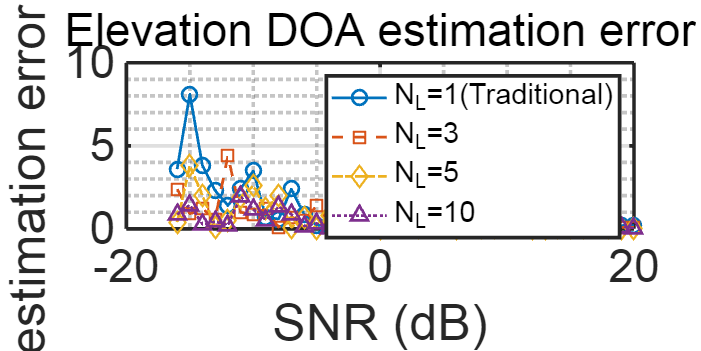

%% 图例设置
legend(biaoqian,...
       'Location', 'northeast', 'FontSize', 16)
%% 其他美化设置
grid minor % 添加次级网格线
% title('仰角不同扩展倍数下的误差', 'FontSize', 14)
title('Elevation DOA estimation error', 'FontSize', 25)

hold off

load("abc._OLD.mat")

%% 数据生成示例（需替换为实际数据）
snr;
% ang_err(1,:,i,1,1,1);
squeeze(ang_err(1,:,i,1,1,1));
%% 绘图设置
figure('Position', [100 100 800 400]) % 设置图像尺寸
hold on; grid on; box on
fprintf('阵元数=%.2f，\n仰角(theta)=%.2f°，\n方位角(phi)=%.2f°\n', ...
            numRX(1),ang_theta(1), ang_phi(2));

阵元数=4.00，
仰角(theta)=18.51°，
方位角(phi)=-35.75°


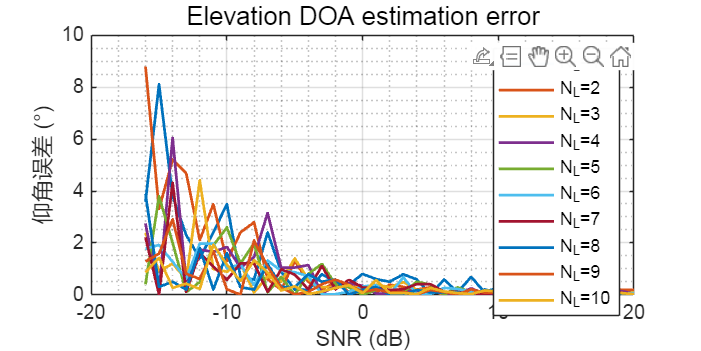

for i =N_L
    plot(snr(9:end), abs(squeeze(ang_err(1,9:end,i,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)
end

% plot(snr(9:end), abs(squeeze(ang_err(1,9:end,1,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)
% plot(snr(9:end), abs(squeeze(ang_err(1,9:end,3,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)
% 
% plot(snr(9:end), abs(squeeze(ang_err(1,9:end,5,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)
% plot(snr(9:end), abs(squeeze(ang_err(1,9:end,10,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)

%% 坐标轴设置
% set(gca, 'YScale', 'log') % Y轴设置为对数坐标
% xlim([-20 20])           % X轴范围
% ylim([1e-5 1])           % Y轴范围
xlabel('SNR (dB)', 'FontSize', 12)
ylabel('仰角误差 (°)', 'FontSize', 12)
set(gca, 'FontSize', 11) % 坐标轴字体大小


biaoqian = arrayfun(@(x) ['N_L=', num2str(x)], N_L, 'UniformOutput', false); % 自动生成标签

%% 图例设置
legend(biaoqian,...
       'Location', 'northeast', 'FontSize', 10)
%% 其他美化设置
grid minor % 添加次级网格线
title('Elevation DOA estimation error', 'FontSize', 14)

hold off

load("abc._OLD.mat")
%% 数据生成示例（需替换为实际数据）
snr;
% ang_err(1,:,i,1,1,1);
squeeze(ang_err(1,:,i,1,1,1));
%% 绘图设置
figure('Position', [100 100 800 400]) % 设置图像尺寸
hold on; grid on; box on
fprintf('阵元数=%.2f，\n仰角(theta)=%.2f°，\n方位角(phi)=%.2f°\n', ...
            numRX(1),ang_theta(1), ang_phi(2));

阵元数=4.00，
仰角(theta)=18.51°，
方位角(phi)=-35.75°


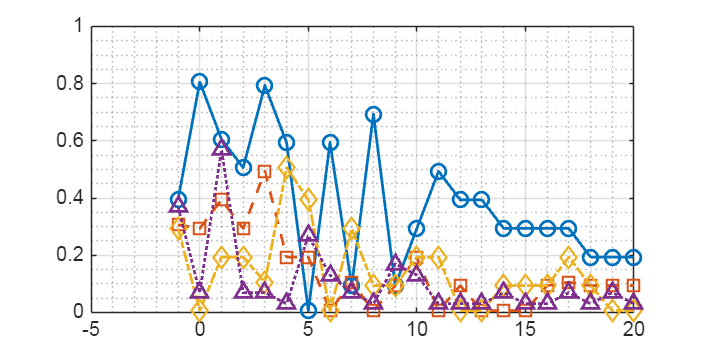

% for i =N_L
%     plot(snr(9:end), abs(squeeze(ang_err(1,9:end,i,1,1,1))), 'MarkerSize', 8, 'LineWidth', 1.5)
% end

plot(snr(24:end), abs(squeeze(ang_err(1,24:end,1,1,1,1))),  'o-','MarkerSize', 8, 'LineWidth', 1.5)
plot(snr(24:end), abs(squeeze(ang_err(1,24:end,3,1,1,1))),  's--','MarkerSize', 8, 'LineWidth', 1.5)

plot(snr(24:end), abs(squeeze(ang_err(1,24:end,5,1,1,1))),  'd-.','MarkerSize', 8, 'LineWidth', 1.5)
plot(snr(24:end), abs(squeeze(ang_err(1,24:end,10,1,1,1))), '^:', 'MarkerSize', 8, 'LineWidth', 1.5)

%% 坐标轴设置
% set(gca, 'YScale', 'log') % Y轴设置为对数坐标
% xlim([-20 20])           % X轴范围
% ylim([1e-5 1])           % Y轴范围
% xlabel('SNR (dB)', 'FontSize', 12)
% ylabel('仰角误差 (°)', 'FontSize', 12)
set(gca, 'FontSize', 11) % 坐标轴字体大小


% biaoqian = arrayfun(@(x) ['N_L=', num2str(x)], [1,3,5,10], 'UniformOutput', false); % 自动生成标签

%% 图例设置
% legend(biaoqian,...
%        'Location', 'northeast', 'FontSize', 10)
%% 其他美化设置
grid minor % 添加次级网格线
% title('仰角不同扩展倍数下的误差', 'FontSize', 14)
hold off

load("aaaa.mat")
data=abs(squeeze(ang_err(2,1,:,1,1,:))')

data =     0.1337    0.1337    0.0337    0.0051    0.0003    0.0118    0.0490    0.0337    0.0369    0.0084
    0.1546    0.0546    0.0546    0.0261    0.0213    0.0092    0.0700    0.0454    0.0160    0.0125
    0.1540    0.2540    0.0460    0.0255    0.2207    0.0086    0.0306    0.0460    0.1835    0.0119
    0.1241    0.0241    0.0241    0.0955    0.0093    0.0214    0.0605    0.0759    0.0465    0.0180
    0.1791    0.0791    0.0209    0.0505    0.0457    0.0664    0.0945    0.0209    0.1085    0.0630
    0.1833    0.1833    0.1167    0.1453    0.2500    0.0621    0.0987    0.1833    0.1127    0.2412
    0.1688    0.0312    0.0312    0.0598    0.0646    0.0233    0.0158    0.0312    0.0982    0.0267
    0.1458    0.0458    0.0458    0.0172    0.0124    0.0003    0.0612    0.0458    0.0752    0.0037
    0.1242    0.0242    0.0242    0.0956    0.0092    0.0213    0.0605    0.0242    0.0464    0.0180
    0.1301    0.0301    0.0301    0.0015    0.0032    0.0847    0.0455    0.0301    

size(data)

ans =     50    10



%% 生成模拟数据（若已有真实数据可跳过）
N_ex = N_L;          % 孔径参数N_ex (0到48,间隔2)
num_reps = 500;         % 蒙特卡洛重复次数

% 生成误差数据矩阵（每个N_ex对应一列）
errorData = data

errorData =     0.1337    0.1337    0.0337    0.0051    0.0003    0.0118    0.0490    0.0337    0.0369    0.0084
    0.1546    0.0546    0.0546    0.0261    0.0213    0.0092    0.0700    0.0454    0.0160    0.0125
    0.1540    0.2540    0.0460    0.0255    0.2207    0.0086    0.0306    0.0460    0.1835    0.0119
    0.1241    0.0241    0.0241    0.0955    0.0093    0.0214    0.0605    0.0759    0.0465    0.0180
    0.1791    0.0791    0.0209    0.0505    0.0457    0.0664    0.0945    0.0209    0.1085    0.0630
    0.1833    0.1833    0.1167    0.1453    0.2500    0.0621    0.0987    0.1833    0.1127    0.2412
    0.1688    0.0312    0.0312    0.0598    0.0646    0.0233    0.0158    0.0312    0.0982    0.0267
    0.1458    0.0458    0.0458    0.0172    0.0124    0.0003    0.0612    0.0458    0.0752    0.0037
    0.1242    0.0242    0.0242    0.0956    0.0092    0.0213    0.0605    0.0242    0.0464    0.0180
    0.1301    0.0301    0.0301    0.0015    0.0032    0.0847    0.0455    0.030

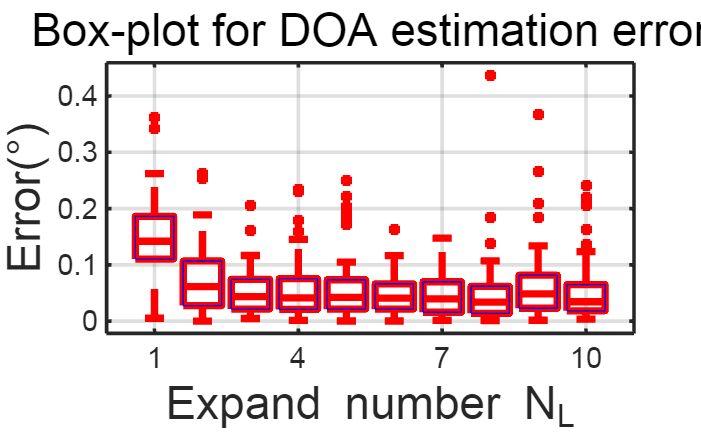


%% 绘制箱线图
figure('Position', [100 100 800 500]) 

% 绘制箱线图（关键参数设置）
boxplot(errorData, 'Colors', 'r', 'Symbol', 'r+', 'Widths', 0.8);
h = findobj(gca, 'Tag', 'Box'); % 获取箱体对象

% 设置箱体样式
for j=1:length(h)
    patch(get(h(j), 'XData'), get(h(j), 'YData'), 'b',...
        'FaceAlpha', 0, 'EdgeColor', 'b'); % 半透明蓝色箱体
end

%% 坐标轴设置
set(gca, 'FontSize', 16)
xlabel('Expand number N_{L}', 'FontSize', 25)
ylabel('Error(°)', 'FontSize', 25)
title('Box-plot for DOA estimation error', 'FontSize', 25)

box on;

% 获取当前坐标轴并加粗线宽
ax = gca;
ax.LineWidth = 2; % 设置线宽为2，数值越大线条越粗

% X轴刻度设置
xticks(1:3:length(N_ex))        % 每3个数据显示一个刻度
xticklabels(N_ex(1:3:end))      % 显示对应的N_ex值
xlim([0 length(N_ex)+1])        % 扩展左右边界

% Y轴范围设置
% ylim([0 ceil(max(errorData(:)))]) 

%% 其他美化
grid on
set(findobj(gca, 'type', 'line'), 'linew', 4) % 加粗所有线条

clear; clc; close all
% 参数设置

params.R_rx = 0.05;
params.r1_radial=900;

params.numRX = 8;
move = 1;
params.N_L = 3;
params.snr=-1;
params.pass_Cf=0;


snr=5;
N_L=1:10;

numRX=6;
ang_theta=rand(50)*80+5;
ang_phi=(rand(50)-0.5)*358;
pass_Cf=1;


ang_err=zeros(2,length(snr),length(N_L),length(pass_Cf),length(numRX),length(ang_theta));
size(ang_err)



for ang=1:length(ang_theta)
    for cf=length(pass_Cf)
        for k=1:length(numRX)
            for i = 1:length(snr)
                for j = 1:length(N_L)
                    params.snr=snr(i);
                    params.N_L = N_L(j);
                    params.tar1_theta=ang_theta(ang);
                    params.tar1_phi=ang_phi(ang);
                    params.pass_Cf=pass_Cf(cf);
                    params.numRX=numRX(k);

                    [theta_list, phi_list] = radar_processing_function(params,move);
                    ang_err(1,i,j,cf,k,ang)=params.tar1_theta-theta_list;
                    ang_err(2,i,j,cf,k,ang)=params.tar1_phi-phi_list;
                end
            end
        end
    end
end

save("aaaa.mat" + ...
    "")